clear all
close all
%% define dei lati e dei giunti
L=[2.5 1 1.5 2.5];
Q=[0.5 1 0.5];
%% calcolo dellle matrix
[M01_ M1_1 M12 M23]=PositionMat(Q,L)

Unrecognized function or variable 'PositionMat'.

%% position of robot
S = DirectRobot(Q,L)
%% plot del robot
plotRobot(Q,L,1)
%% definizioni variabili simboliche
% Q=(sym('q', [1 3]))
% L=(sym('l', [1 4]))
% %% definizione della cinematica diretta
% [M01_ M1_1 M12 M23]=PositionMat(Q,L)
% M01=M01_*M1_1
% M02=M01*M12
% M03=M02*M23
% Sg = M03*[0 0 0 1]'
% %% calcolo jacobiana
% J = jacobian(Sg(1:end-1),Q);
% J = matlabFunction(J)%conbversione in matlab function to use it
J_=JacRobot(Q,L)
Q=TR4_invNumeric([4 1 1],Q,L,100)
S=DirectRobot(Q,L)

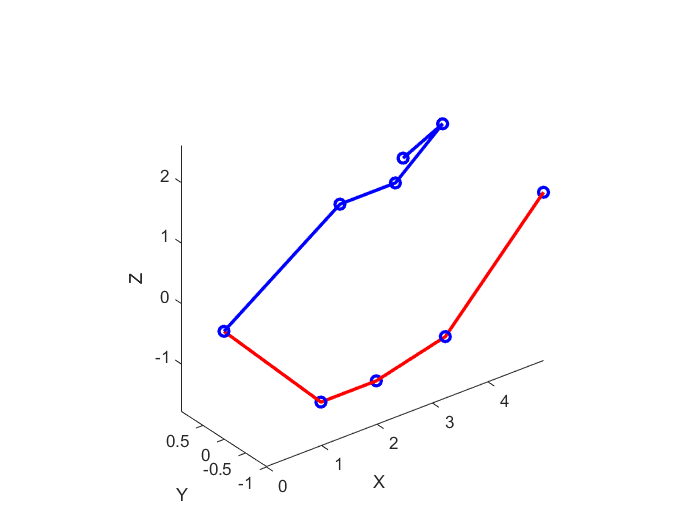

close all
clear all

L=[2.5 1 1.5 2.5];
Si=[4 1 1];
Sf=[5 -1 1];
Qi=TR4_invNumeric(Si,[0.5 0.5 0.5],L,50);
Qf=TR4_invNumeric(Sf,[0.5 0.5 0.5],L,50);
TR4_plot(Qi,L,'b',1)
TR4_plot(Qf,L,'r',1)

[Q,T]=TR4_linearMov([Si' Sf'],@Cicloidale,5,L);

ans = 2

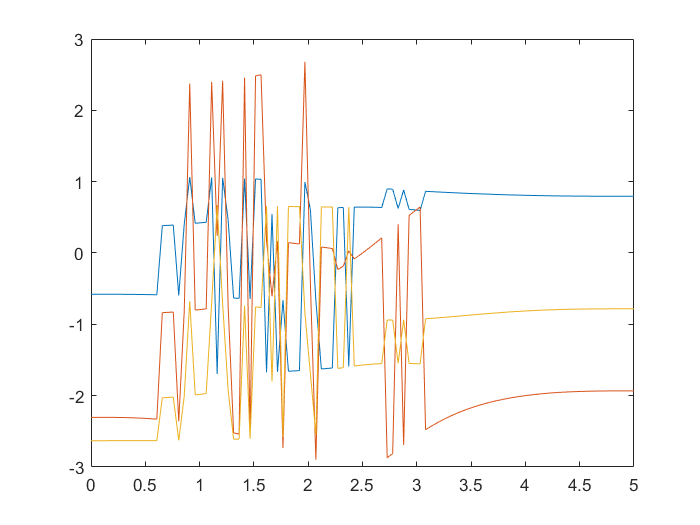

figure
plot(T(1,:),Q(:,:,1),T(1,:),Q(:,:,2),T(1,:),Q(:,:,3))

figure
Jy1=0.427;Jz1=Jy1;Jg1=Jz1;
Jy2=0.286;Jz2=Jy2;Jg2=Jy2;
Jy3=0.0533;Jz3=Jy3;Jg3=Jz3;
g1=0.48;g2=0.42;g3=0.24;
m1=8;m2=7;m3=4;
Jx1=0;Jx2=Jx1;Jx3=Jx1;
Jxy=0;Jxz=0;Jyz=0;

J1_1=calcJ(Jx1,Jy1,Jz1,Jxy,Jyz,Jxz,m1,[L(2) 0 0],[g1 0 0]);
J2_2=calcJ(Jx2,Jy2,Jz2,Jxy,Jyz,Jxz,m2,[L(3) 0 0],[g2 0 0]);
J3_3=calcJ(Jx3,Jy3,Jz3,Jxy,Jyz,Jxz,m3,[L(4) 0 0],[g3 0 0]);

T = 5;
n= 100;
St = [];
Vt = [];
At = [];
Sp=[];
F3=[];
F2=[];
F1=[];
tt = zeros(0,100);


Lrz = [0 -1 0 0;
    1  0 0 0;
    0  0 0 0;
    0  0 0 0];

Lry = -[0  0 1 0;
    0  0 0 0;
    -1  0 0 0;
    0  0 0 0];
Hg=[0 0 0 0;
    0 0 0 0;
    0 0 0 -9.81;
    0 0 0 0];


for i = 1:n
    f=[0 0 0 1;
        0 0 0 1;
        0 0 0 1;
        -1 -1 -1 0];
    t=(i-1)*T/(n-1); % time from 0 to T with step dT
    tt(i) = t;
    t=2.3667;
    [Q1(i),Q1p(i),Q1pp(i)] = Cicloidale(t,T,Qi(1),Qf(1)-Qi(1));
    [Q2(i),Q2p(i),Q2pp(i)] = Cicloidale(t,T,Qi(2),Qf(2)-Qi(2));
    [Q3(i),Q3p(i),Q3pp(i)] = Cicloidale(t,T,Qi(3),Qf(3)-Qi(3));
    
    Q = [Q1(i),Q2(i),Q3(i)];
    Qp = [Q1p(i),Q2p(i),Q3p(i)];
    Qpp = [Q1pp(i),Q2pp(i),Q3pp(i)];
    
    [M01,M12,M23,M03] = matrixRRR(Q,L);
    s = M03(:,4);
    St = [St s];
    
    M02 = M01*M12;
    
    w01_0 = Lrz*Qp(1); %speed in 0-1 referece system 0
    w12_0 = M01*Lrz*Qp(2)*inv(M01); %speed in 1-2 referece system 0
    w23_0 = M02*Lry*Qp(3)*inv(M02); %speed in 2-3 the referece system 0

    w02_0 = w01_0 + w12_0; %speed in 0-2 referece system 0 (sum 0-1 % 1-2)
    w03_0 = w02_0 + w23_0; %speed in 0-3 referece system 0 (sum 0-2 % 2-3) gripper velocity seen by 0

    sp = w03_0*s;
    Sp = [Sp sp];

    h01_0 = (Lrz*Qpp(1) + Lrz^2*Qp(1)^2); %acceleration in 0-1 referece system 0
    h12_0 = M01*(Lrz*Qpp(2) + Lrz^2*Qp(2)^2)*inv(M01); %acceleration in 1-2 referece system 0
    h23_0 = M02*(Lry*Qpp(3) + Lry^2*Qp(3)^2)*inv(M02); %acceleration in 2-3 referece system 0

    h02_0 = h01_0 + h12_0 + 2*w01_0*w12_0; %acc in 0-2 referece system 0 (sum 0-1 % 1-2 and coriolis between them)
    h03_0 = h02_0 + h23_0 + 2*w02_0*w23_0; %acc in 0-3 referece system 0 (sum 0-2 % 2-3 and coriolis between them)
    Vt = [Vt w03_0*s];
    At = [At h03_0*s];
    J01_0=M01*J1_1*M01';
    J02_0=M02*J2_2*M02';
    J03_0=M03*J3_3*M03';    
    
    F3=[F3 skew(h03_0*J03_0)-skew(Hg*J03_0)+f];
    F2=[F2 skew(h02_0*J02_0)-skew(Hg*J02_0)+F3(end)];
    F1=[F1 skew(h01_0*J01_0)-skew(Hg*J01_0)+F2(end)];
    
end
hold on
plot3(St(1,:),St(2,:),St(3,:),"LineWidth",3,"Color",'g')
figure()
plot(tt,St(1,:),tt,St(2,:),tt,St(3,:))
legend("x","y","z")
figure()
plot(tt,Vt(1,:),tt,Vt(2,:),tt,Vt(3,:))
legend("x","y","z")
figure()
ATN1=diff(Vt(1,:))/(tt(2)-tt(1));
ATN2=diff(Vt(2,:))/(tt(2)-tt(1));
ATN3=diff(Vt(3,:))/(tt(2)-tt(1));
plot(tt,At(1,:),tt,At(2,:),tt,At(3,:))
hold on
plot(tt(1:end-1),ATN1,tt(1:end-1),ATN2,tt(1:end-1),ATN3)
legend("x","y","z","x diff","y diff","z diff")
